## Week 10

### Data Access - Part 1

I'd like to start off this week by talking about ways of obtaining data files online. In the last class, we briefly touched on this. I am mostly talking about obtaining data files that various agencies store online. There is great variability in this, in terms of file formats, and (current topic) the mode of accessing those data files.

So, let's first talk about FTP (file transfer protocol) access. FTP is not as common as it once was, but many government agencies still use it. For this example we will consider data (climate 'normals', or 30-year averages) from NOAA. They live at a particular FTP site, given below.

clear all
close all
clc

web('ftp://ftp.ncdc.noaa.gov/pub/data/normals/1981-2010/')

The above command, on a mac will open up a 'login' prompt. This FTP site is 'anonymous' which means you don't need credentials. So, select 'guest' and click connect.

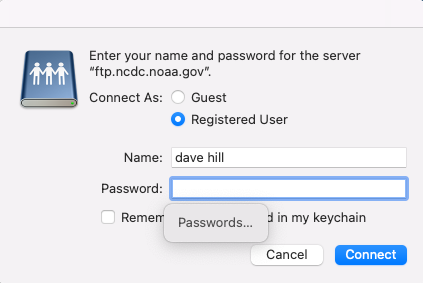

On a mac, this will bring up a Finder window.

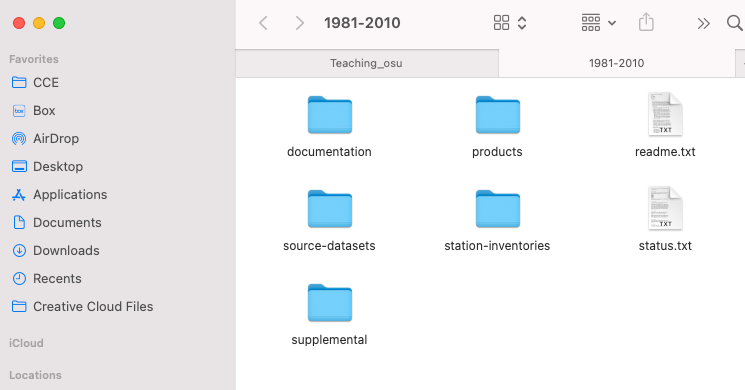

At this point, I can navigate around, find, and download some file of interest. For example, I could go into the products folder, and then precipitation, and then I'd see a bunch of files like this:

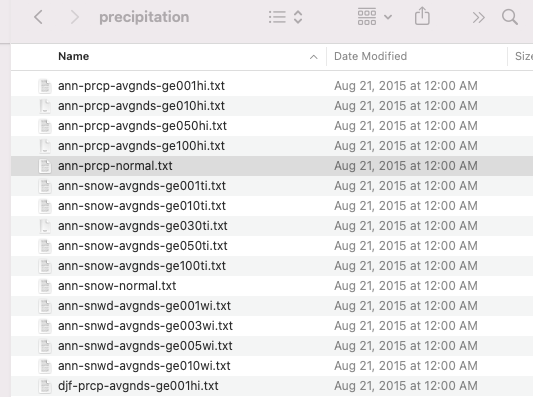

Great. So you can copy over whatever files you want.

However, this process is kind of tedious. It would be really nice to be able to write some code to automate tasks associated with finding and downloading data. Especially in cases where the data archive is dynamic (adding new files each eay, month, or year) and you would like to go grab 'updates' or newly added files. 

%We start by creating a FTP object.
ts=ftp('ftp.ncdc.noaa.gov');

This essentially opens the door for us. Now we need to move around to the particular folder we want. So where are we? We can use basic command line commands like we saw in the first week of class. For example, lets just do a directory listing

ls

ann-prcp-normal.txt	sample.nc		tempdata.mlapp		testfile.nc		week10_ftp.mlx		week10_netcdf.mlx



Hmmm...That just displayed our 'local' directory listing (ie., on our computer) How do we see a directory listing at the place we just connected to?

dir(ts)

 
data         has          pub          welcome.msg                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                    

Nice...that shows us the directory structure at the NOAA site. Now, we need to change directory into products, and dov another listing once we are there

cd(ts,'pub/data/normals/1981-2010/products');
dir(ts)

 
auxiliary      hourly         precipitation  station        temperature                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                               

you'll notice several folders to choose from. Let's try precip and then once again look at the listing

cd(ts,'precipitation')

ans = '/pub/data/normals/1981-2010/products/precipitation'

dir(ts)

 
ann-prcp-avgnds-ge001hi.txt  ann-prcp-avgnds-ge010hi.txt  ann-prcp-avgnds-ge050hi.txt  ann-prcp-avgnds-ge100hi.txt  ann-prcp-normal.txt          ann-snow-avgnds-ge001ti.txt  ann-snow-avgnds-ge010ti.txt  ann-snow-avgnds-ge030ti.txt  ann-snow-avgnds-ge050ti.txt  ann-snow-avgnds-ge100ti.txt  ann-snow-normal.txt          ann-snwd-avgnds-ge001wi.txt  ann-snwd-avgnds-ge003wi.txt  ann-snwd-avgnds-ge005wi.txt  ann-snwd-avgnds-ge010wi.txt  djf-prcp-avgnds-ge001hi.txt  djf-prcp-avgnds-ge010hi.txt  djf-prcp-avgnds-ge050hi.txt  djf-prcp-avgnds-ge100hi.txt  djf-prcp-normal.txt          djf-snow-avgnds-ge001ti.txt  djf-snow-avgnds-ge010ti.txt  djf-snow-avgnds-ge030ti.txt  djf-snow-avgnds-ge050ti.txt  djf-snow-avgnds-ge100ti.txt  djf-snow-normal.txt          djf-snwd-avgnds-ge001wi.txt  djf-snwd-avgnds-ge003wi.txt  djf-snwd-avgnds-ge005wi.txt  djf-snwd-avgnds-ge010wi.txt  dly-prcp-25pctl.txt          dly-prcp-50pctl.txt          dly-prcp-75pctl.txt          dly-prcp-pctall-ge001hi.txt  dly-prcp-pct

So, what is there is a bunch of data files. The particular structure, etc. of those files is not that important for this exercise. How do we get the data? Let's try the annual precip file. After running this, make sure thatthe file shows up in your folder on your local machine!

mget(ts,'ann-prcp-normal.txt')

note the use of the * wildcard below to get ALL of the files that start with ann-prcp. So, this is a way to quickly and easily download many files.

mget(ts,'ann-prcp*')

ans = 15×1 cell array
    {'/Users/dfh/Library/CloudStorage/Box-Box/Hill_Sync/Teaching/Teaching_osu/CE640_OC512/matlab_class/scripts/week10/ann-prcp-avgnds-ge001hi.txt'}
    {'/Users/dfh/Library/CloudStorage/Box-Box/Hill_Sync/Teaching/Teaching_osu/CE640_OC512/matlab_class/scripts/week10/ann-prcp-avgnds-ge010hi.txt'}
    {'/Users/dfh/Library/CloudStorage/Box-Box/Hill_Sync/Teaching/Teaching_osu/CE640_OC512/matlab_class/scripts/week10/ann-prcp-avgnds-ge050hi.txt'}
    {'/Users/dfh/Library/CloudStorage/Box-Box/Hill_Sync/Teaching/Teaching_osu/CE640_OC512/matlab_class/scripts/week10/ann-prcp-avgnds-ge100hi.txt'}
    {'/Users/dfh/Library/CloudStorage/Box-Box/Hill_Sync/Teaching/Teaching_osu/CE640_OC512/matlab_class/scripts/week10/ann-prcp-normal.txt'        }
    {'/Users/dfh/Library/CloudStorage/Box-Box/Hill_Sync/Teaching/Teaching_osu/CE640_OC512/matlab_class/scripts/week10/ann-snow-avgnds-ge001ti.txt'}
    {'/Users/dfh/Library/CloudStorage/Box-Box/Hill_Sync/Teaching/Teaching_osu/CE640_OC512/

close(ts);